## Parámetros

rotacion = 0;
factor = 4/3; %1 a 4/3
lmin = 15;
es = 3.5;
hojas = 4;
n = 3000;

lcx = 20;
lcy = 9;

q10 = 170*(pi/180);
q20 = -160*(pi/180);

%Valores iniciales de los angulos
q10i = q10;
q20i = q20;

l1 = 19;
l2 = 18;

## Trébol estilizado

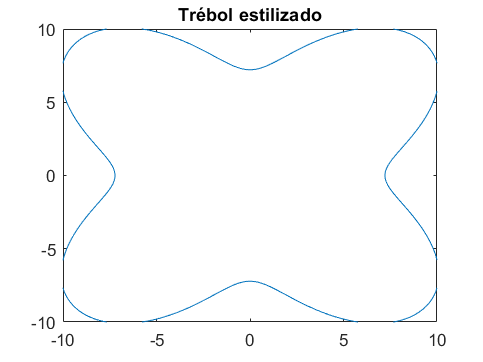

[r,theta]=trayectoria0(rotacion,lmin, factor,es,hojas,n);

xp = r.*cos(theta);
yp = r.*sin(theta);
plot(xp,yp)
title('Trébol estilizado')
a = ((lmin/2)*factor)*(1+sin(rotacion));
xlim ([-a a])
ylim ([-a a])

## Trasladando al origen

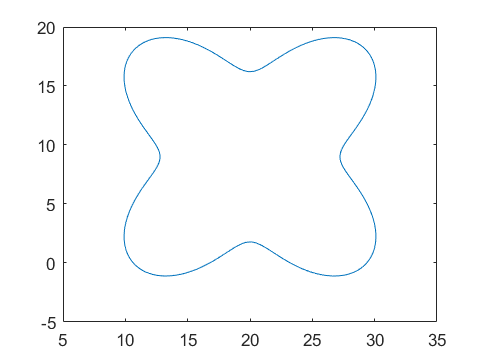

[x,y]=Totrigen(lcx,lcy,theta,r);
plot(x,y)

## Cinemática inversa

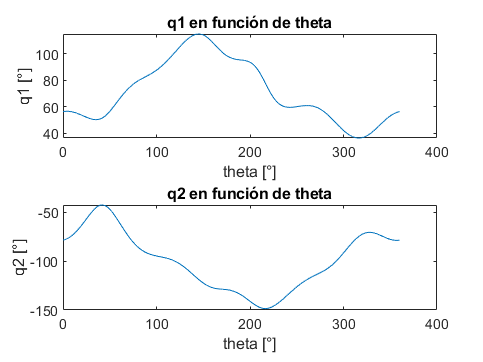

q1 = zeros(length(x),1);
q2 = zeros(length(x),1);
for i = 1:length(x)
    [q1(i), q2(i)] = Cinversa(l1,l2,x(i),y(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
end

figure()
subplot(2,1,1);
plot((theta)*(180/pi),q1*(180/pi))
title('q1 en función de theta')
ylabel('q1 [°]')
xlabel('theta [°]')

subplot(2,1,2); 
plot(theta*(180/pi),q2*(180/pi))
title('q2 en función de theta')
ylabel('q2 [°]')
xlabel('theta [°]')

## Trayectoria de acercamiento

[x20, y20] = Cdirecta(l1,l2,q10i,q20i); %Posición inicial extremo distal
pos = (n/2) + 1; %Aprox en pi
[x2f, y2f] = Totrigen(lcx,lcy,theta(pos),r(pos));
Xaprox = linspace(x20,x2f,100);
Yaprox = linspace(y20,y2f,100);
% figure()
% hold on
% plot(Xaprox,Yaprox)
% plot(x,y)
% hold off

## Visualización

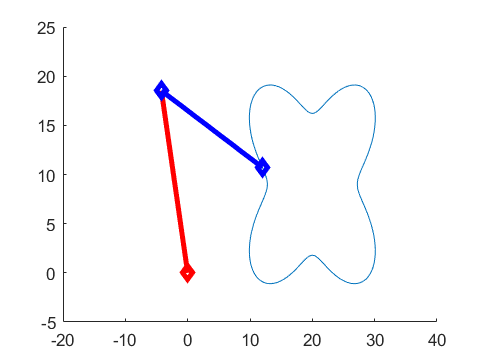

%Vectores de la posición distal del mecanismo en todo momento
XTotal = [Xaprox, x(1,pos:end), x(1,1:pos-1)];
YTotal = [Yaprox, y(1,pos:end), y(1,1:pos-1)];

%Cinematica inversa de todo el movimiento
q1 = zeros(1,length(XTotal));
q2 = zeros(1,length(YTotal));
figure(); %creamos la figura para visualizar
for i = 1:length(x)
    %Cinematica inversa
    [q1(i), q2(i)] = Cinversa(l1,l2,XTotal(i),YTotal(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
    %Gráfica
    cla;    %clear axes
    hold on
    plot(x,y);%Trebol base
    %Primer eslabon
    x1 = l1*cos(q1(i));
    y1 = l1*sin(q1(i));
    %Segundo eslabon
    x2 = XTotal(i);
    y2 = YTotal(i);
    plot([0 x1],[0 y1],'rd-','LineWidth',3)
    plot([x1 x2],[y1 y2],'bd-','LineWidth',3)
    pause(0.00001);
    xlim([-20 40]);
    ylim([-5 25]);
end


% figure()
% hold on
% x1 = l1*cos(q1(end));
%     y1 = l1*sin(q1(end));
%     %Segundo eslabon
%     x2 = XTotal(end);
%     y2 = YTotal(end);
%     plot([0 x1],[0 y1],'rd-','LineWidth',3)
%     plot([x1 x2],[y1 y2],'bd-','LineWidth',3)